## Figure 4 things

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';

%load 
load S.mat;

## Load the data

%get the indentation
Sn="S6";
Tn="T16";

%get the spike data relative to this ind
fbgs=S.(Sn).(Tn).FBGs; fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
roi=S.(Sn).(Tn).ROI;
ind=S.(Sn).(Tn).Ind;

%timing limits
tmin=min(neurons(:,1))-1;
limits=[0 max(neurons(:,1))+1-tmin];
motors(:,1)=motors(:,1)-tmin;


%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

## Create the signals

%timing issues
tc=0.0001; %s
tau=0.010; %s
g=1;
a=tc/(tau+tc);
a=0.0005;
T=1; %s
N=T/tc;
time=(1:tc:1+T)'; time(end)=[]; %ms

%create the 23 signals
ys=zeros(N,23);
for i=1:23

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=zeros(N,1);
    x=zeros(N,1);
    [~,closestIndex] = min(abs(time-spiketimes'));
    x(closestIndex)=1;

    %filtering operation
    for n=1:(N-1)    
        y(n+1)=g*a*x(n)+(1-a)*y(n);
    end
    y(1)=0; y(end)=0;
    
    %save the signal
    ys(:,i)=y;
end

## Run simulink simulation

runsimulation=0;
if runsimulation
    data1=[time ys(:,6)*6500];
    data2=[time ys(:,11)*6500];
    data3=[time ys(:,16)*6500];
    
    %run simulink m8 for figure;
    out=sim("test_haptic_skin_scheduler_vtrial_m8_forfigure");

    % get signals
    t=out.tout;
    X=out.simout;

    %save the data
    save('t','t');
    save('X','X');
else
    load('t.mat');
    load('X.mat');
end

## Visualize the pulses

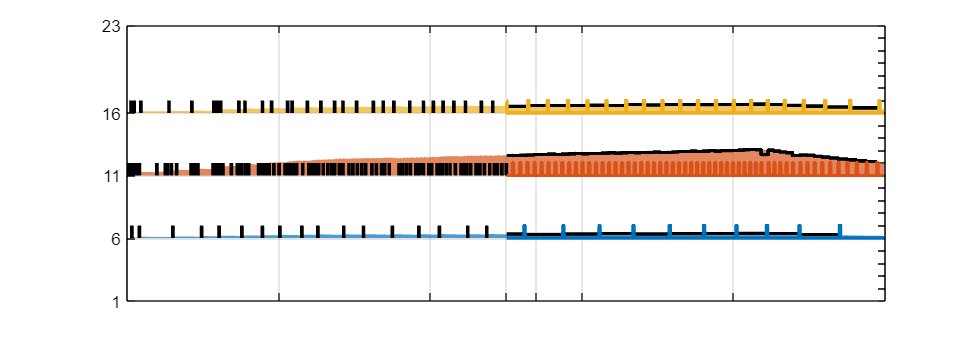

sub=figure('Units','centimeters','Position',[4 1 26 9]); hold on;
%
visualizerscale=1;
%xline

xtresh=1.5;
xtresh2=1.5;

grid on; 

C=colororder;
%recall and plot the signals
c=0;
for i=1:23

    %signals containers
    y=ys(:,i);

    %result
    timep=time;
    yp=y;
    yp(1)=0; yp(end)=0;
    if any(y)
        c=c+1;
        fill(timep,visualizerscale*100*yp+i,0,'FaceColor',C(c,:),'FaceAlpha',0.7,'EdgeColor','none');
    end
end


% %plot all the spikes as lines
for i=1:length(ids)
    if allspikes(i)<=xtresh
        line([allspikes(i) allspikes(i)], [ids(i) ids(i)+1],'Linewidth',2,'Color','k');
    end
end

ylim([1 23]);
yticks([1 6 11 16 23]);

xlim([1 2]);
box on;
motorlines=[6 11 16];

td=time;
Xd=X(2:end,:)-X(1:end-1,:);
Xd(Xd<=0)=0;
for i=1:size(X,2)
    
    %initialize freqs
    freqs=nan(size(td));
    
    %find the t of rising edges
    edges=td(Xd(:,i)==1);
    
    %find the deltat between adjacent t
    diffs=edges(2:end)-edges(1:end-1); 
    diffs=[diffs; 0];
    
    %istantaneous frequency is inversion of deltat
    freqs(Xd(:,i)==1)=1./diffs;
    freqt=freqs(~isnan(freqs));
    freqsint=fillmissing(freqs,"previous");
    
    %report
    ix=td>xtresh2;
    tdn=td(ix);
    freqsint=freqsint(ix);
    % freqsint(1)=0; freqsint(end)=0;
    plot(tdn,visualizerscale*freqsint*100/6500+motorlines(i),'LineWidth',2,'Color','k');  grid on;
    %scatter(edges, freqt,5,'filled','o','k');
end
% fill(t,out.simout1(:,1),0,'FaceColor',C(1,:),'FaceAlpha',0.3,'EdgeColor','none');
% fill(t,out.simout1(:,2)+100,0,'FaceColor',C(2,:),'FaceAlpha',0.3,'EdgeColor','none');
% fill(t,out.simout1(:,2),0); 
% xlabel('Time [s]');

ix=t>xtresh2;
plot(t(ix),X(ix,1)+6,"Color",C(1,:),'LineWidth',2);
plot(t(ix),X(ix,2)+11,"Color",C(2,:),'LineWidth',2);
plot(t(ix),X(ix,3)+16,"Color",C(3,:),'LineWidth',2);


yyaxis right

% ylabel('Frequencies [Hz]');
ylim([1 23]);
yticks(1:23);
labels=[1:5 0:20:80 0:20:80 0:20:80 1:3]';
labels=labels/visualizerscale;
celllabels=arrayfun(@num2str, labels, 'UniformOutput', false);
celllabels(1:5)={''};
celllabels(21:23)={''};
yticklabels("");
% 
% 
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
ax.YAxis(2).FontSize = 8;
blocks=[1.5 1.5085 1.5180 1.5237 1.5275 1.5287 1.5370];
xline(xtresh2);
yyaxis left
% xline(gca,blocks,'LineWidth',2,'Color',[1 0 0],'Alpha',0.2);
% for i=1:length(blocks)
%     text(blocks(i),1.5,sprintf('%.3f',blocks(i)),'Color','k','FontWeight','normal','FontSize',3);
% end
xticks([1 1.2 1.4 1.5 1.54 1.6 1.8 2]);
xticklabels("")
hold off;  %xlim([0 1000]); box on;  ylim([1.5 6]);
%export
saveas(sub,'subfigures/sub.fig');
exportgraphics(sub, 'subfigures/sub.png', 'ContentType', 'image','Resolution',300);
exportgraphics(sub, 'subfigures/sub.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);